# Speed Polars

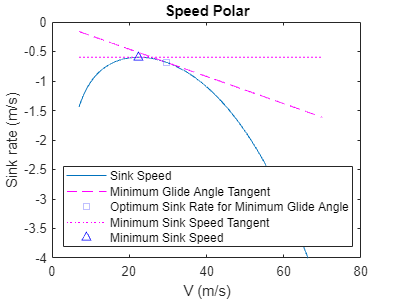

clc
clear all

A = 29; % Aspect ratio
e = 0.9; % Oswald efficiency facotr
W2S = 500; % Wing loading N/m^2
T_nonstand = 10; % Temperature offset deg C of non standard day
alt_des = 3000; % Desired altitude m
[rho,~] = Nonstandardrho(alt_des, T_nonstand);
C_D_0 = 0.0109; % Parasite drag coefficient
V = 7:0.01:70; % Velocity range MAKE SURE SPACING OF THESE VALUES MATCHES 

[V_sink, V_sinktan1, pt1, gamma_opt, L_D_optgam, V_optgam, V_sinkoptgam, C_L_optgam, V_sinktan2, pt2, V_sinkmin, gamma_sinkmin, L_D_sinkmin, V_atsinkmin, C_L_sinkmin] = V_sink(rho, A, e, C_D_0, W2S, V);
speedpolarplot(V,V_sink, V_sinktan1, pt1, V_sinktan2, pt2)